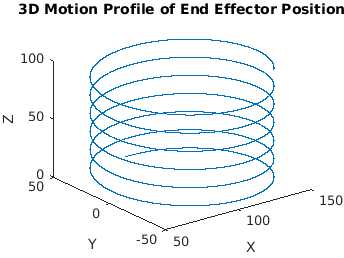

plot3(data(:,1), data(:,2), data(:,3));
xlabel('X')
ylabel('Y')
zlabel('Z')
title('3D Motion Profile of End Effector Position')


figure
hold on
legend on

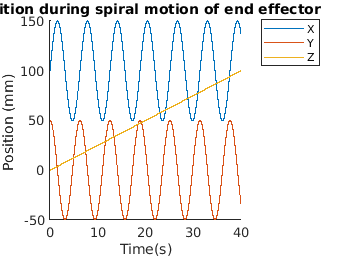

legend('Location','bestoutside')
plot(data(:,4),data(:,1),'DisplayName','X');
plot(data(:,4),data(:,2),'DisplayName','Y');
plot(data(:,4),data(:,3),'DisplayName','Z');
xlabel('Time(s)');
ylabel('Position (mm) ');
title('Position during spiral motion of end effector')



figure
hold on
legend on

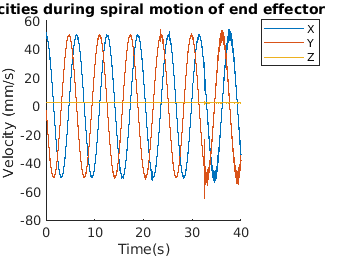

legend('Location','bestoutside')
plot(data(:,4),(gradient(data(:,1)) ./ gradient(data(:,4))),'DisplayName','X');
plot(data(:,4),(gradient(data(:,2)) ./ gradient(data(:,4))),'DisplayName','Y');
plot(data(:,4),(gradient(data(:,3)) ./ gradient(data(:,4))),'DisplayName','Z');
xlabel('Time(s)');
ylabel('Velocity (mm/s) ');
title('Velocities during spiral motion of end effector')


figure
hold on
legend on

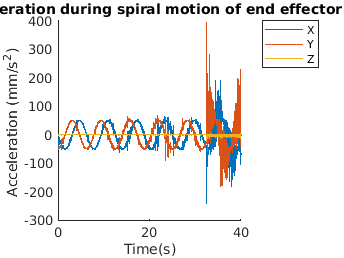

legend('Location','bestoutside')

plot(data(:,4),movmean(gradient(gradient(data(:,1)) ./ gradient(data(:,4)))./ gradient(data(:,4)),100,1),'DisplayName','X');
plot(data(:,4),movmean(gradient(gradient(data(:,2)) ./ gradient(data(:,4)))./ gradient(data(:,4)),100,1),'DisplayName','Y');
plot(data(:,4),movmean(gradient(gradient(data(:,3)) ./ gradient(data(:,4)))./ gradient(data(:,4)),100,1),'DisplayName','Z');
xlabel('Time(s)');
ylabel('Acceleration (mm/s^2) ');
title('Acceleration during spiral motion of end effector')